# DC_LAB3_AngularVelocity

addpath("plot\");
addpath("Linearization\");
addpath("Modeling\");

## 1. Figure out Steady State 

### 1) Rising time 2.5[sec]

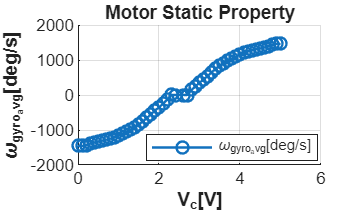

plot_sweep('../data/Static/Static_0.1.out');

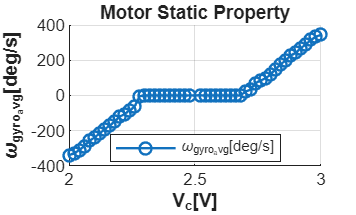

plot_sweep('../data/Static/Static_0.02.out');

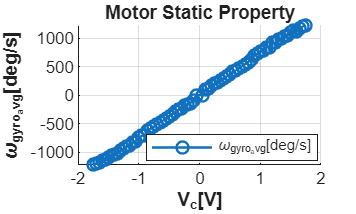

Get_fitting_Quadratic('../data/Static/Static_0.05.out');


plot_sweep('../data/Static_Linear/Static.out');

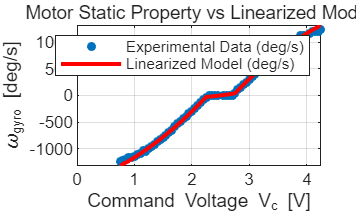

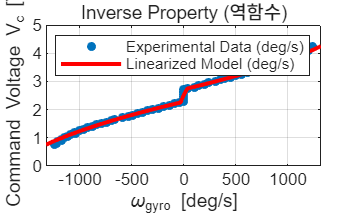

Linear_mapping('../data/Static/Static_0.05.out');  

## 2. Obtain Static Motor Property

### 1) Dead-zone at 2.3[V] -> 2.7[V] voltage

### 2) Saturation of Wgyro to 25 [rad/ses] (219 rpm)  (3.66 Hz)

### 3) Linear region positive from 2.7[V] to 3.5[V], negative from 2.3[V] to 1.5[V]

% plot_Wgyro('Slewrate');
% 
% find_coff(0.05, 0.2302, 1.842, 2.72, 2.85, 4.80);
% find_coff(-0.05,-0.2436,-1.7824,2.28,2.15,0.3);


## 3. Validation - triangle

파일을 찾을 수 없습니다: ../data/Validation/Valid_tri_iter23.out


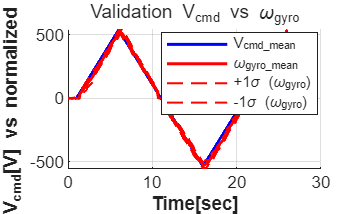

Vali_plot('tri');

파일을 찾을 수 없습니다: ../data/Validation/Valid_sin_iter11.out
파일을 찾을 수 없습니다: ../data/Validation/Valid_sin_iter12.out
파일을 찾을 수 없습니다: ../data/Validation/Valid_sin_iter13.out
파일을 찾을 수 없습니다: ../data/Validation/Valid_sin_iter14.out
파일을 찾을 수 없습니다: ../data/Validation/Valid_sin_iter15.out
파일을 찾을 수 없습니다: ../data/Validation/Valid_sin_iter16.out
파일을 찾을 수 없습니다: ../data/Validation/Valid_sin_iter17.out
파일을 찾을 수 없습니다: ../data/Validation/Valid_sin_iter18.out
파일을 찾을 수 없습니다: ../data/Validation/Valid_sin_iter19.out
파일을 찾을 수 없습니다: ../data/Validation/Valid_sin_iter20.out
파일을 찾을 수 없습니다: ../data/Validation/Valid_sin_iter21.out
파일을 찾을 수 없습니다: ../data/Validation/Valid_sin_iter22.out
파일을 찾을 수 없습니다: ../data/Validation/Valid_sin_iter23.out


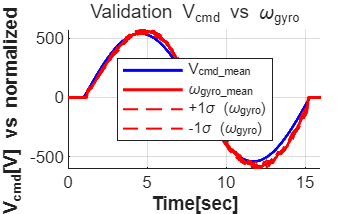

Vali_plot('sin');

## 4. Bode 

%From now on, the path is unified: 
path = '..\data\BodeMag\';

generate_bode_plot(path); 

## 5-1. Obtain Transfer Function  

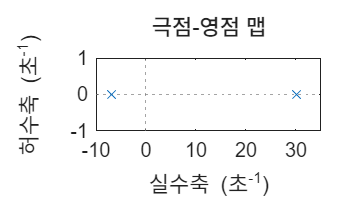


--- Identified Transf5er Function ---
 
num/den = 
 
            -385.2912
   --------------------------
   s^2 - 23.0301 s - 209.6522


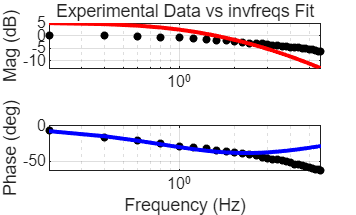

Trans_func(path);

## 5-2. Validation

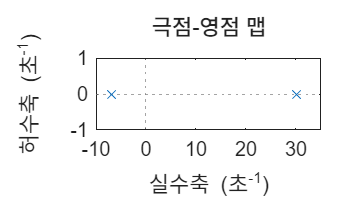


--- Identified Transf5er Function ---
 
num/den = 
 
            -385.2912
   --------------------------
   s^2 - 23.0301 s - 209.6522


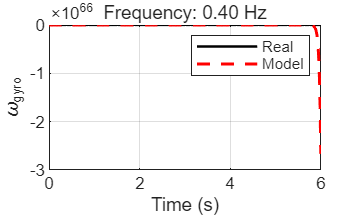

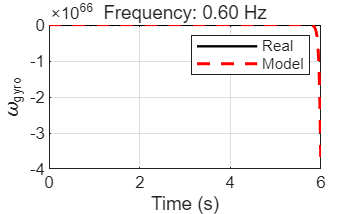

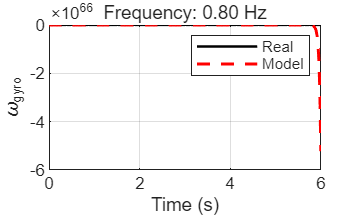

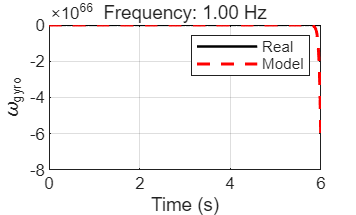

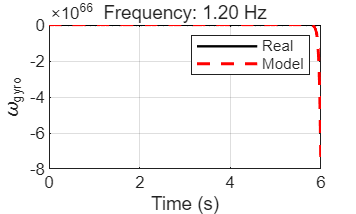

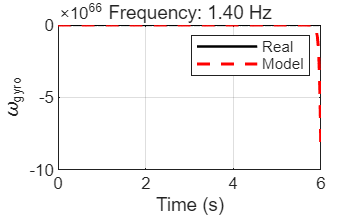

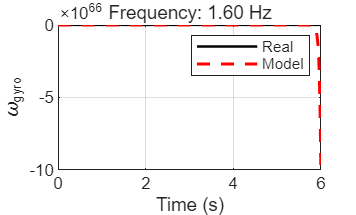

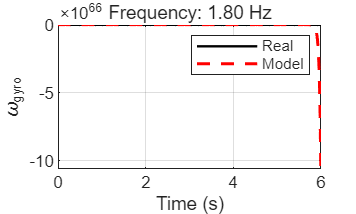

Trans_func_valid(path); 